# **Implementación EC en matlab de modulación digital y analógica**

Andrés Fernando Jerez Medina - 2190416

Jorge Eduardo Angarita Perez - 2190427

Sergio Sebastián Oliveros Sepulveda - 2190396 

## **Punto 2:**

Al igual que en ejercicio anterior, fue necesario iniciar introduciendo los parámetros requeridos. Siendo el primero de estos la frecuencia del mensaje, la cual ya es fija y vale 100 Hz. Después, se tomaron las frecuencias de portadora y muestreo, siendo estas 10 y 100 veces la frecuencia del mensaje respectivamente. Se usó el parámetro *nper* para que el tiempo de observación fueran exactamente 2 periodos de la señal mensaje.

fm = 100;                    %Frecuencia del mensaje

Ac = 1;                      %Amplitud de la portadora
fc = fm*10;                  %Frecuencia de la portadora
fs = fc*10;                  %Frecuencia de muestreo
Ts = 1/fs;                   %Periodo de muestreo

nper = 2;                    %Periodos de la señal
Tend = 1/fm*nper;            %Tiempo de simulación

Finalmente, se escogió el valor de $D_f$ teniendo en cuenta la siguiente fórmula encontrada en el libro de comunicaciones analógicas y digitales de León Couch, la cual relaciona la máxima desviación de frecuencia en una modulación FM con el anterior parámetro:


$$\Delta \;f_{\textrm{máx}} =D_f \frac{V_p }{2\pi \;}$$


Donde $V_p$ es el máximo de la señal $m\left(t\right)$, por lo que despejando, se tiene $D_f$ dada una desviación máxima deseada, la cual en este caso fue de 300 para poder detallar mejor los cambios de frecuencia:

dfMax = 500;                 %Desviación máxima
Df = 2*pi/10*dfMax;          %Constante de desviación de frecuencia en modulador

Con esto se pudo definir la función mensaje:

t = 0:Ts:(Tend-Ts);          %Tiempo
n = length(t);               %Número de muestras
m_t = 10*sin(2*pi*fm*t);     %Construcción de la señal mensaje 

Ahora, a partir de esto último construimos las funciones $x\left(t\right)$ y$y\left(t\right)$  de la siguiente manera:


$$x\left(t\right)=A_c \cos \left(D_f \int_{-\infty }^t m\left(\alpha \;\right)d\alpha \;\right)$$



$$y\left(t\right)=A_c \sin \left(D_f \int_{-\infty }^t m\left(\alpha \;\right)d\alpha \;\right)$$


Para esto se definió previamente un $D_f$ de 100 y debido a que es modulación en frecuencia la amplitud de portadora se estableció como 1. Se puede observar también, que ambos componentes dependen de un valor correspondiente a la multipicación de $D_f$ con la integral del mensaje, al estar en el dominio discreto esta integral fue definida como una sumatoria de cada uno de valores (usando *cumsum*) multiplicado por el tiempo de muestreo:   

x_t = Ac*cos(Df*cumsum(m_t)*Ts);                %Componente en fase
y_t = Ac*sin(Df*cumsum(m_t)*Ts);                %Componente en cuadratura
g_t = x_t + 1j*y_t;                             %Envolvente compleja

s_t = x_t.*cos(2*pi*fc*t)-y_t.*sin(2*pi*fc*t);  %Señal modulada

Las señales obtenidas fueron graficadas en el tiempo usando el vector *t *antes definido. A continuación, pueden observarse las 4 gráficas, del mensaje, las partes real e imaginaria de la envolvente compleja y la modulación $s\left(t\right)$.

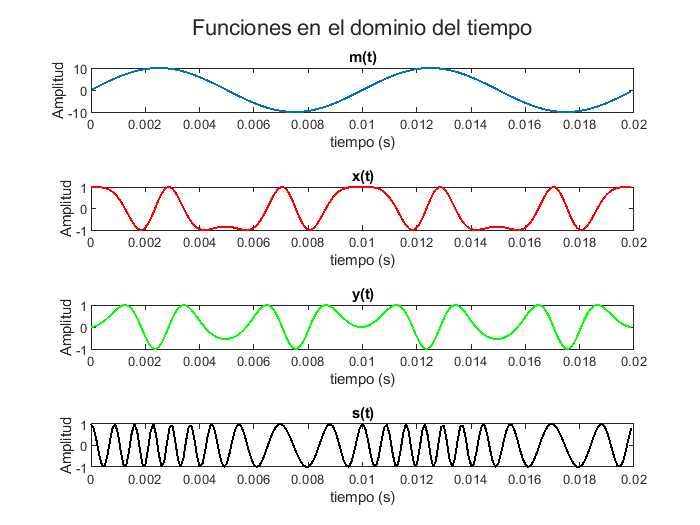

p = tiledlayout(4,1);
title(p,"Funciones en el dominio del tiempo")

nexttile; plot(t,m_t,'LineWidth',1.2); title("m(t)"); 
ylabel("Amplitud"); xlabel("tiempo (s)");

nexttile; plot(t,x_t,'red','LineWidth',1.2); title("x(t)"); 
ylabel("Amplitud"); xlabel("tiempo (s)");

nexttile; plot(t,y_t,'green','LineWidth',1.2); title("y(t)"); 
ylabel("Amplitud"); xlabel("tiempo (s)");

nexttile; plot(t,s_t,'black','LineWidth',1.2); title("s(t)"); 
ylabel("Amplitud"); xlabel("tiempo (s)");

Para observar el espectro de las señales en el dominio de la frecuencia se realizó la tranformada de Fourier de cada función:

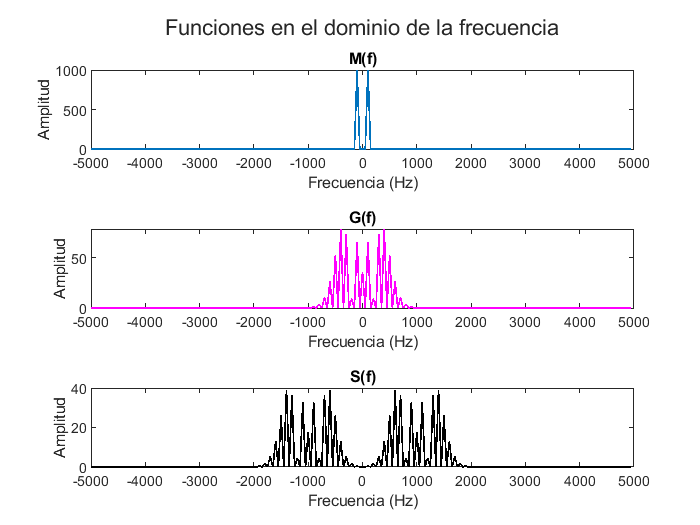

m_f = fftshift(fft(m_t));
g_f = fftshift(fft(g_t));
s_f = fftshift(fft(s_t));

f = (-n/2:n/2 - 1)*(fs/n);
figure
t = tiledlayout(3,1);
title(t,"Funciones en el dominio de la frecuencia")

nexttile; plot(f,abs(m_f),'LineWidth',1); title("M(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,abs(g_f),'magenta','LineWidth',1); title("G(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,abs(s_f),'black','LineWidth',1); title("S(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")

Y por último, se muestra la densidad espectral de potencia (PSD) de cada una de las señales vistas anteriormente:

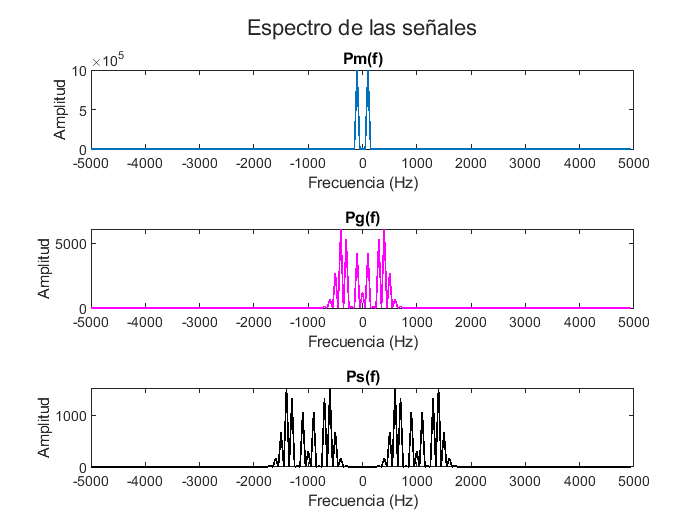

figure
t = tiledlayout(3,1);
title(t,"Espectro de las señales")
nexttile; plot(f,(abs(m_f).^2),'LineWidth',1); title("Pm(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,(abs(g_f).^2),'magenta','LineWidth',1); title("Pg(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,(abs(s_f).^2),'black','LineWidth',1); title("Ps(f)"); 
ylabel("Amplitud"); xlabel("Frecuencia (Hz)")

Como se puede observar en las señales mostradas, la señal modulada cambia en su frecuencia a medida que el mensaje también cambia, cuando el mensaje toma valores pequeños la frecuencia de la señal modulada decrece y entre mayor sea el mensaje mayor es la frecuencia de la señal modulada, nótese que la amplitud de la señal final es constante debido a que es modulación FM.

En el dominio de la frecuencia se puede observar que el espectro de la señal modulada es el resultado de desplazar la envolvente compleja (la cuál contiene el mensaje) a una frecuencia mayor. La frecuencia central de estos espectros es 1000 Hz debido a que este es el valor de la frecuencia de la portadora. 